# Milling and Welding Todo

I have solved for you as an example the drilling task. Similar procedure ought to be done with welding task

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º among the two cylinder axis

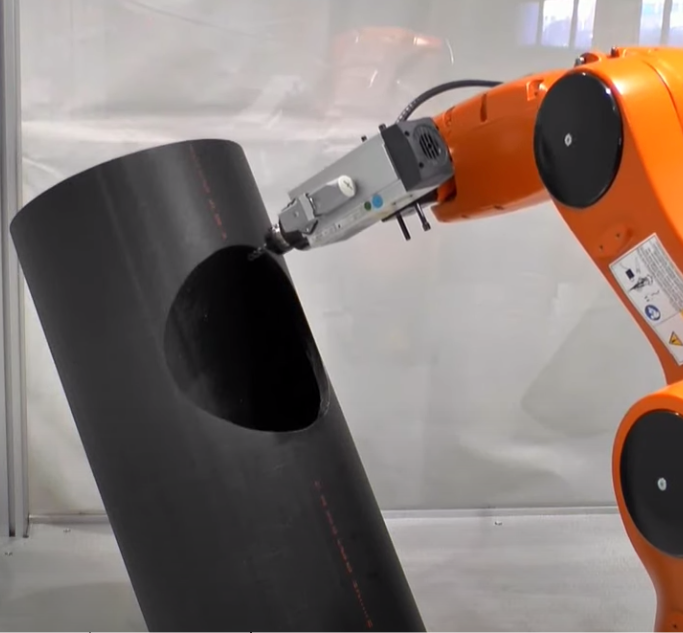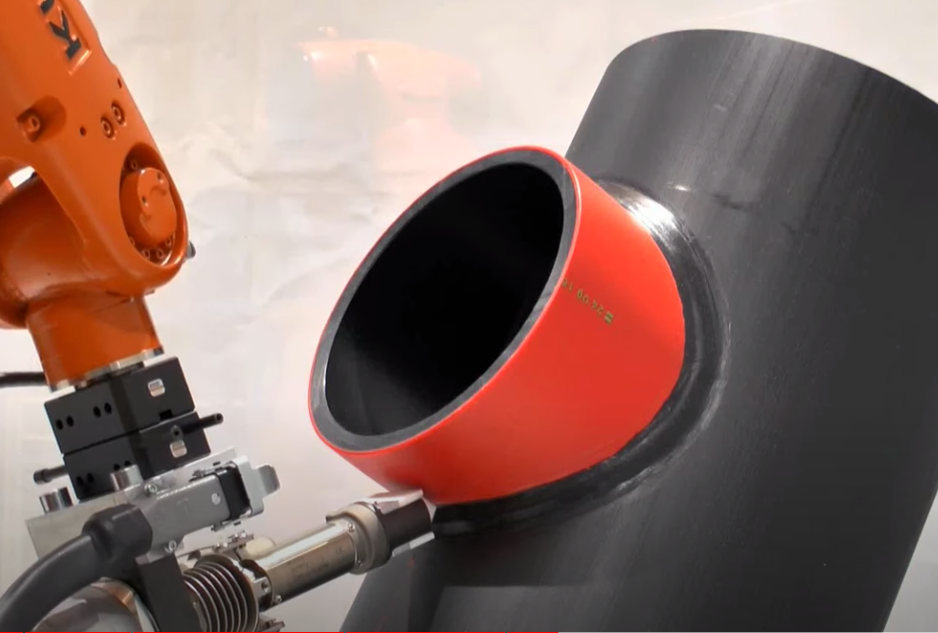

## Load the cylinder data

clear;
close all;
clf
load('F_V_cylinder.mat');

## **Plot the robot to initial position**

Pay attention how to move the robot base and add a tool

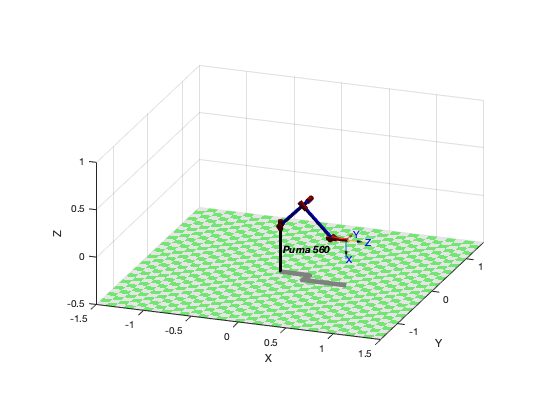

radius=0.20;
mdl_puma560;
p560.base = transl(-0.1, 0, 0);
p560.tool=transl(0,0,0.15);
p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
hold on

## Visualize the cylinder

Cy_scale=0.25

Cy_scale = 0.2500

CY_pose=transl([-0.3 0.3 -0.35])*troty(-pi/6) * trotx(-pi/6)

CY_pose =     0.8660    0.2500   -0.4330   -0.3000
         0    0.8660    0.5000    0.3000
    0.5000   -0.4330    0.7500   -0.3500
         0         0         0    1.0000


V_cy_drill = CY_pose*[Cy_scale.*V_cy'; ones(1,length(V_cy))] 

V_cy_drill =    -0.0835   -0.1063   -0.1291   -0.1519   -0.1747   -0.1974   -0.2202   -0.2430   -0.2658   -0.2886   -0.3114   -0.3342   -0.3570   -0.3798   -0.4026   -0.4253   -0.4481   -0.4709   -0.4937   -0.5165   -0.0755   -0.0983   -0.1210   -0.1438   -0.1666   -0.1894   -0.2122   -0.2350   -0.2578   -0.2806   -0.3034   -0.3262   -0.3489   -0.3717   -0.3945   -0.4173   -0.4401   -0.4629   -0.4857   -0.5085   -0.0761   -0.0988   -0.1216   -0.1444   -0.1672   -0.1900   -0.2128   -0.2356   -0.2584   -0.2812
    0.3000    0.3263    0.3526    0.3789    0.4053    0.4316    0.4579    0.4842    0.5105    0.5368    0.5632    0.5895    0.6158    0.6421    0.6684    0.6947    0.7211    0.7474    0.7737    0.8000    0.3422    0.3686    0.3949    0.4212    0.4475    0.4738    0.5001    0.5264    0.5528    0.5791    0.6054    0.6317    0.6580    0.6843    0.7107    0.7370    0.7633    0.7896    0.8159    0.8422    0.3829    0.4092    0.4355    0.4618    0.4881    0.5144    0.5407    0.5671    0.

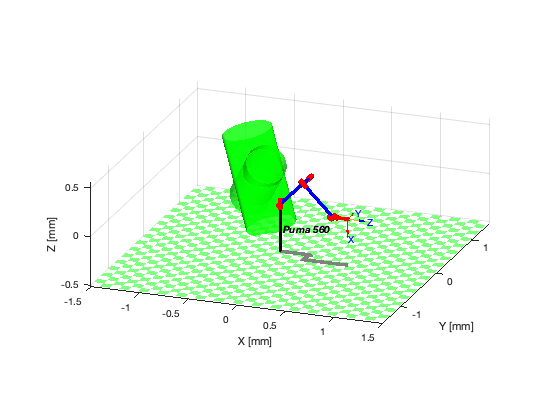

FVsPlot(F_cy,V_cy_drill(1:3,:)',[0 1 0])

welded_cylinder_pose = CY_pose * transl(0,0,0.5) * trotx(-pi/2) * troty(-pi/4) * transl(0,0,-0.35);
V_welded_cylinder_drill = welded_cylinder_pose * [radius .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy,V_welded_cylinder_drill(1:3,:)',[0 1 0])

## Draw drill task profile

Drill hole center 'D_h_c'

D_h_c = CY_pose * transl(0,0,0.5) * trotx(-pi/2) * troty(-pi/4) * transl(0,0,-0.25)

D_h_c =     0.7891    0.4330   -0.4356   -0.4076
    0.6124   -0.5000    0.6124    0.3969
    0.0474   -0.7500   -0.6597    0.1899
         0         0         0    1.0000


Drill poses

n=60

n = 60

for i=1:n
Drill_Pose(:,:,i)= D_h_c * trotz(2*pi*i/n) * transl(radius, 0,0) * trotx(-pi/4) * troty(-pi/4);
end

Plotting Drill poses. Notice 'z' axis of the poses 

cir=transl(Drill_Pose)'

cir =    -0.2416   -0.2352   -0.2307   -0.2282   -0.2276   -0.2290   -0.2324   -0.2376   -0.2448   -0.2537   -0.2643   -0.2765   -0.2901   -0.3050   -0.3210   -0.3380   -0.3557   -0.3740   -0.3927   -0.4115   -0.4303   -0.4489   -0.4669   -0.4844   -0.5010   -0.5166   -0.5310   -0.5440   -0.5555   -0.5654   -0.5736   -0.5800   -0.5845   -0.5870   -0.5876   -0.5862   -0.5828   -0.5776   -0.5704   -0.5615   -0.5509   -0.5387   -0.5251   -0.5102   -0.4942   -0.4772   -0.4595   -0.4412   -0.4225   -0.4037
    0.5083    0.4959    0.4825    0.4681    0.4530    0.4372    0.4210    0.4045    0.3880    0.3715    0.3554    0.3396    0.3246    0.3103    0.2969    0.2847    0.2736    0.2640    0.2557    0.2491    0.2440    0.2406    0.2390    0.2390    0.2408    0.2443    0.2495    0.2563    0.2647    0.2744    0.2856    0.2979    0.3113    0.3257    0.3408    0.3566    0.3728    0.3893    0.4058    0.4223    0.4384    0.4542    0.4693    0.4836    0.4969    0.5092    0.5202    0.5299    0.5381   

hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);
%axis([-1.5 1.5 -1.5 1.5 -0.5 1])
axis equal
trplot(Drill_Pose(:,:,1), 'length',0.2)
trplot(Drill_Pose(:,:,15), 'length',0.2)
trplot(Drill_Pose(:,:,30), 'length',0.2)
trplot(Drill_Pose(:,:,45), 'length',0.2)

## Executing the drilling task

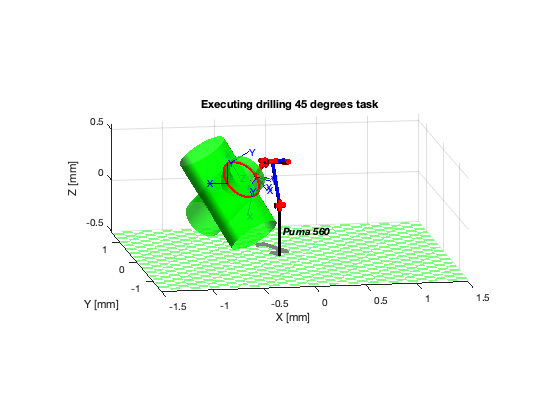

Q = p560.ikine6s(Drill_Pose, 'run');
p560.plot(Q,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
% Para grabarlo comentar el plot de arriba y descomentar el de abajo
%p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],...
%    'trail','-','jaxes','zoom',2,'movie', 'drilling_45_grados.mp4')
title("Executing drilling 45 degrees task")

## Functions

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end
